# Deflection Analysis of Bracket

This example shows how to analyze a 3-D mechanical part under an applied load using finite element analysis (FEA) and determine the maximal deflection.

**Create Structural Analysis Model**

The first step in solving a linear elasticity problem is to create a structural analysis model. This is a container that holds the geometry, structural material properties, damping parameters, body loads, boundary loads, boundary constraints, superelement interfaces, initial displacement and velocity, and mesh.

model = createpde('structural','static-solid');

**Import Geometry**

Import an STL file of a simple bracket model using the `importGeometry` function. This function reconstructs the faces, edges and vertices of the model. It can merge some faces and edges, so the numbers can differ from those of the parent CAD model.

importGeometry(model,'BracketWithHole.stl');

Plot the geometry, displaying face labels.

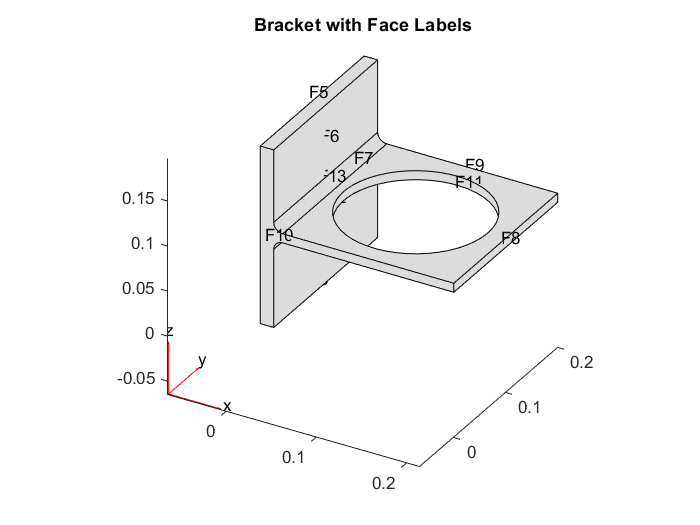

figure(11)
pdegplot(model,'FaceLabels','on')
view(30,30);
title('Bracket with Face Labels')

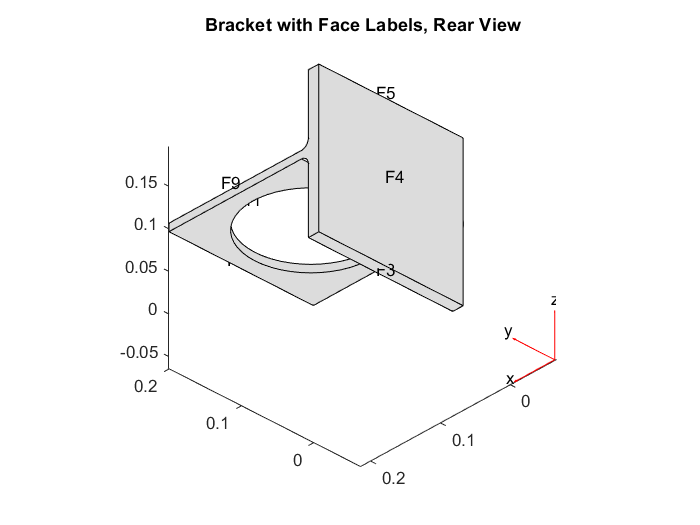


figure(12)
pdegplot(model,'FaceLabels','on')
view(-134,-32)
title('Bracket with Face Labels, Rear View')

**Specify Structural Properties of Material**

Specify Young's modulus and Poisson's ratio of the material.

structuralProperties(model,'YoungsModulus',200e9, ...
                           'PoissonsRatio',0.3);

**Apply Boundary Conditions and Loads**

The problem has two boundary conditions: the back face (face 4) is fixed, and the front face has an applied load. All other boundary conditions, by default, are free boundaries.

structuralBC(model,'Face',4,'Constraint','fixed');

Apply a distributed load in the negative *z*-direction to the front face (face 8).

structuralBoundaryLoad (model,'Face',8,'SurfaceTraction',[0;0;-1e4]);

**Generate Mesh**

Generate and plot a mesh.

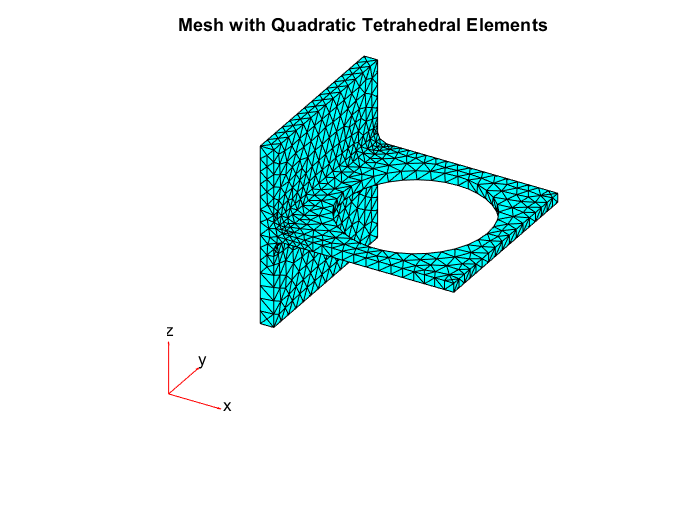

generateMesh(model);
figure(13)
pdeplot3D(model)
title('Mesh with Quadratic Tetrahedral Elements');

**Calculate Solution**

Use the `solve` function to calculate the solution.

result = solve(model)

result =   StaticStructuralResults with properties:

      Displacement: [1×1 FEStruct]
            Strain: [1×1 FEStruct]
            Stress: [1×1 FEStruct]
    VonMisesStress: [5993×1 double]
              Mesh: [1×1 FEMesh]


**Examine Solution**

Find the maximal deflection of the bracket in the *z*-direction.

minUz = min(result.Displacement.uz);
fprintf('Maximal deflection in the z-direction is %g meters.', minUz)

Maximal deflection in the z-direction is -4.43075e-05 meters.

**Plot Displacement Components**

Plot the components of the solution vector. The maximal deflections are in the *z*-direction. Because the part and the loading are symmetric, the *x*-displacement and *z*-displacement are symmetric, and the *y*-displacement is antisymmetric with respect to the center line.

Here, the plotting routine uses the `'jet'` colormap, which has blue as the color representing the lowest value and red representing the highest value. The bracket loading causes face 8 to dip down, so the maximum *z*-displacement appears blue.

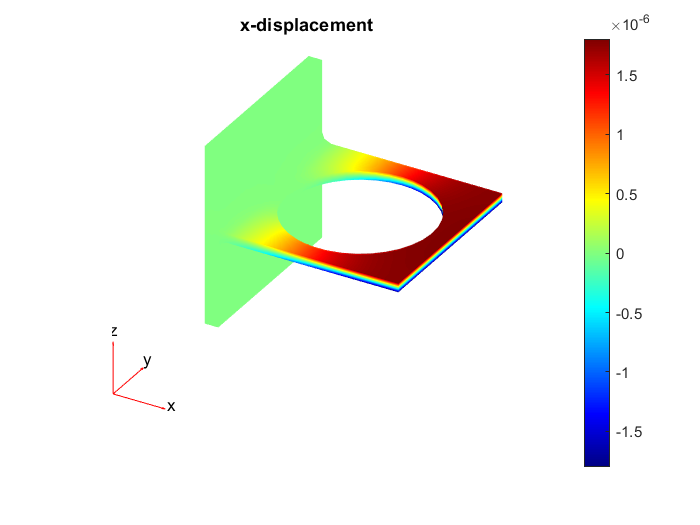

figure(14)
pdeplot3D(model,'ColorMapData',result.Displacement.ux)
title('x-displacement')
colormap('jet')

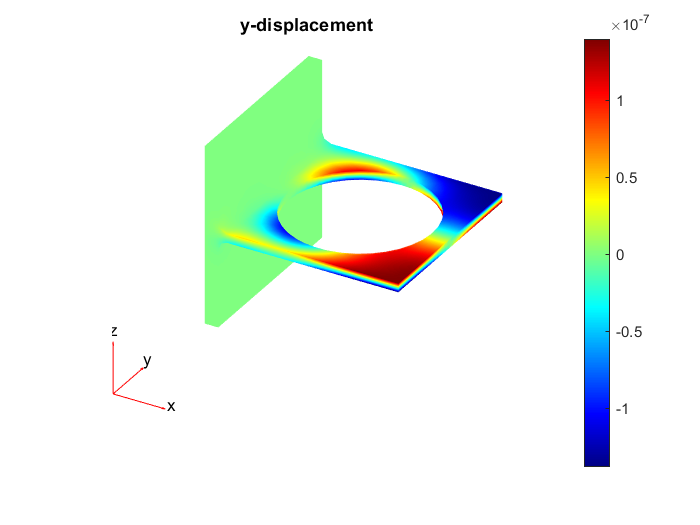


figure(15)
pdeplot3D(model,'ColorMapData',result.Displacement.uy)
title('y-displacement')
colormap('jet')

pdeplot3D(model,'ColorMapData',result.Displacement.uy)
title('y-displacement')
colormap('jet')

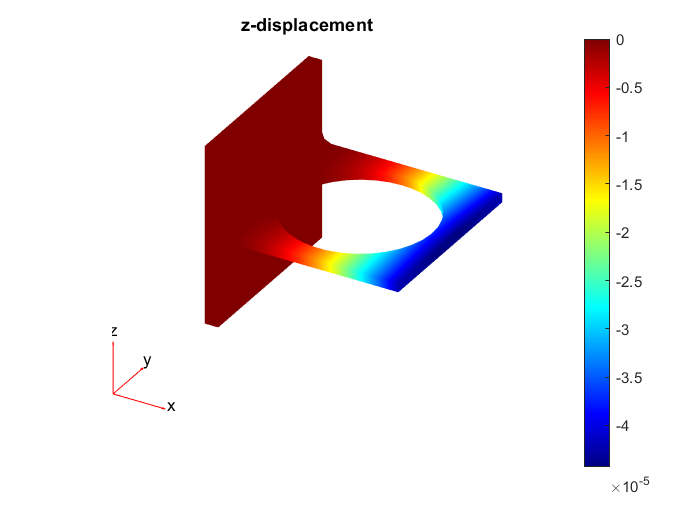


figure(16)
pdeplot3D(model,'ColorMapData',result.Displacement.uz)
title('z-displacement')
colormap('jet')

**Plot von Mises Stress**

Plot values of the von Mises stress at nodal locations. Use the same `jet` colormap.

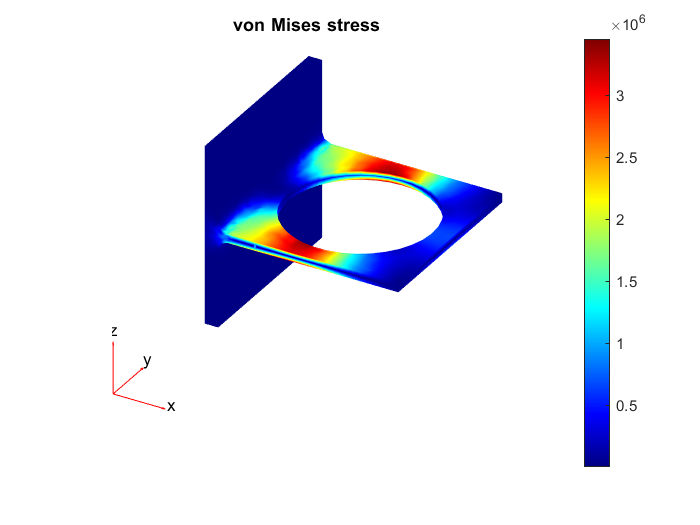

figure(17)
pdeplot3D(model,'ColorMapData',result.VonMisesStress)
title('von Mises stress')
colormap('jet')